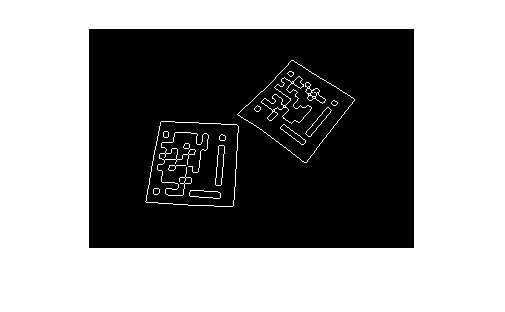

%Build 0.1 - Guideline-Detection (2019-11-19)

%TestImage1 = imread('im2.jpg');
%TestImage1 = imread('im4.png');
TestImage1 = imread('image1.png');
%TestImage1 = imread("training_1.jpg");

TestImage1 = imsharpen(TestImage1);

TestImage1 = imresize(TestImage1, 0.5);
%TestImage1 = imrotate(TestImage1, -45);

TestG = rgb2gray(TestImage1);



bw = edge(TestG);

MaxPixels = 10;



[L,num] = bwlabel(bw);

counts = sum(bsxfun(@eq,L(:),1:num));
B1 = bsxfun(@eq,L,permute(find(counts>MaxPixels),[1 3 2]));
L2 = sum(B1,3)>0;

imshow(L2);


%Find regions
s = regionprops(L2,{...
    'Centroid',...
    'MajorAxisLength',...
    'MinorAxisLength',...
    'Orientation'});

TotalShapes = length(s);

Guidelines = struct;
GuidelinesS = struct;
GuidelinesL = struct;
Cornerstones = struct;

% GuidelinesS.Centroid = [0 0];
% GuidelinesS.MajorAxisLength = 0;
% GuidelinesS.MajorAxisLength = 0;
% GuidelinesS.Orientation = 0;

MinSRatio = 3;
MaxSRatio = MinSRatio + 6;

PotentialGuideS = 0;
PotentialGuideL = 0;
PotentialCornerstones = 0;

for i = 1:TotalShapes
    Shape = s(i);
    ShapePos = Shape.Centroid;
    ShapeLength = Shape.MajorAxisLength;
    ShapeWidth = Shape.MinorAxisLength;
    ShapeAngle = Shape.Orientation;
    
    %Get Ratio
    ShapeRatio = ShapeLength/ShapeWidth;
    
    %Store Guides
    if ShapeRatio > MinSRatio && ShapeRatio < MaxSRatio 
        PotentialGuideS = PotentialGuideS + 1;

        Guidelines(PotentialGuideS).Centroid = ShapePos;
        Guidelines(PotentialGuideS).MajorAxisLength = ShapeLength;
        Guidelines(PotentialGuideS).MinorAxisLength = ShapeWidth;
        Guidelines(PotentialGuideS).Orientation = ShapeAngle;
    
    else
        %Check cornerstones
        if ShapeRatio > 0.7 && ShapeRatio < 1.2
            PotentialCornerstones = PotentialCornerstones + 1;
            
            Cornerstones(PotentialCornerstones).Centroid = ShapePos;
            Cornerstones(PotentialCornerstones).MajorAxisLength = ShapeLength;
            Cornerstones(PotentialCornerstones).MinorAxisLength = ShapeWidth;
            Cornerstones(PotentialCornerstones).Orientation = ShapeAngle;
        end

    end
end

TotalS = 0;
TotalL = 0;
ConfirmedMarkers = struct;

%Verify Shapes
for j = 1:PotentialGuideS
    Shape = Guidelines(j);
    ShapePos = Shape.Centroid;
    ShapeLength = Shape.MajorAxisLength;
    ShapeWidth = Shape.MinorAxisLength;
    ShapeAngle = Shape.Orientation;
    
    for k = 1:PotentialGuideS
        Shape2 = Guidelines(k);
        ShapePos2 = Shape2.Centroid;
        ShapeLength2 = Shape2.MajorAxisLength;
        ShapeWidth2 = Shape2.MinorAxisLength;
        ShapeAngle2 = Shape2.Orientation;
        
        dGuide = norm(ShapePos - ShapePos2);
        dAngle = abs(ShapeAngle - ShapeAngle2);
        
        Min = 2.5*ShapeWidth;
        Max = 7*ShapeWidth;
        
        if dGuide >=  Min && dGuide <  Max ...
            && dAngle > 75 && dAngle < 100
       
            %Short
            if  ShapeLength < ShapeLength2
                TotalS = TotalS + 1;
                GuidelinesS(TotalS).Centroid = ShapePos;
                GuidelinesS(TotalS).MajorAxisLength = ShapeLength;
                GuidelinesS(TotalS).MinorAxisLength = ShapeWidth;
                GuidelinesS(TotalS).Orientation = ShapeAngle;
            end
            
            %Long
%             if ShapeLength > ShapeLength2
%                 TotalL = TotalL + 1;
%                 GuidelinesL(TotalL).Centroid = ShapePos2;
%                 GuidelinesL(TotalL).MajorAxisLength = ShapeLength2;
%                 GuidelinesL(TotalL).MinorAxisLength = ShapeWidth2;
%                 GuidelinesL(TotalL).Orientation = ShapeAngle2;
%             end
        end
        
    end
    
end

ConfirmedMarkers = zeros(length(s), 4);
TotalMarkers = 0;

%Verify Cornerstones
for Apex = 1:PotentialCornerstones
    Shape = Cornerstones(Apex);
    ShapePos = Shape.Centroid;
    
    for CornerA = 1:PotentialCornerstones
        ShapeA = Cornerstones(CornerA);
        ShapePosA = ShapeA.Centroid;
        
        for CornerB = 1:PotentialCornerstones
            ShapeB = Cornerstones(CornerB);
            ShapePosB = ShapeB.Centroid;
            
            dApexA = norm(ShapePos - ShapePosA);
            dApexB = norm(ShapePos - ShapePosB);
            dCorner = norm(ShapePosA - ShapePosB);
            
            Angle = acos((dApexA^2 + dApexB^2 - dCorner^2)/(2*dApexA*dApexB))*180/pi;
            
            Max = Shape.MinorAxisLength*14;
            Min = Shape.MinorAxisLength*6;
            
            MaxC = Shape.MinorAxisLength*12;
            MinC = Shape.MinorAxisLength*6;
            
            if Angle > 75 && Angle < 100 ...
                    && dApexA > Min && dApexA < Max ...
                        && dApexB > Min && dApexB < Max ...
                            && dCorner > MinC && dCorner < MaxC
                        
                        %Find Matching Short Guide Bar
                        for Guide = 1:TotalS
                            GuidePos = GuidelinesS(Guide).Centroid;
                            
                            dApexGuide = norm(GuidePos - ShapePos);
                            dCornerAGuide = norm(GuidePos - ShapePosA);
                            dCornerBGuide = norm(GuidePos - ShapePosB);
                            
                            
                            MaxDistance = 12*Shape.MinorAxisLength;
                            MinDistance = 8*Shape.MinorAxisLength;
                            
                            if dApexGuide > MinDistance && dApexGuide < MaxDistance ...
                                    && dCornerBGuide > dCornerAGuide
                                TotalMarkers = TotalMarkers + 1;
                                ConfirmedMarkers(TotalMarkers, :) = [Apex CornerA CornerB Guide];
                            end
                        end
            end
        end
    end
end

%Get Marker
for Marker = 1:TotalMarkers
    ApexPos = Cornerstones(ConfirmedMarkers(Marker, 1)).Centroid;
    APos = Cornerstones(ConfirmedMarkers(Marker, 2)).Centroid;
    BPos = Cornerstones(ConfirmedMarkers(Marker, 3)).Centroid;
    GPos = GuidelinesS(ConfirmedMarkers(Marker, 4)).Centroid;
    
end

%Plot coordinates
imshow(TestImage1);
hold on
for Marker = 1:TotalMarkers
    for Guide = 1:4
        Index = ConfirmedMarkers(Marker, Guide);
        
        if Guide <= 3
            Position = Cornerstones(Index).Centroid;
        else
            Position = GuidelinesS(Index).Centroid;
        end
        
        x = Position(1);
        y = Position(2);
        
        plot(x, y, 'r+', 'LineWidth', 2, 'MarkerSize', 10);
    end
end
hold off
% t = linspace(0,2*pi,50);
% 
% s = GuidelinesS;
% 
% imshow(TestImage1);
% hold on
% for k = 1:length(s)
%     a = s(k).MajorAxisLength/2;
%     b = s(k).MinorAxisLength/2;
%     Xc = s(k).Centroid(1);
%     Yc = s(k).Centroid(2);
%     phi = deg2rad(-s(k).Orientation);
%     x = Xc + a*cos(t)*cos(phi) - b*sin(t)*sin(phi);
%     y = Yc + a*cos(t)*sin(phi) + b*sin(t)*cos(phi);
%     plot(x,y,'r','Linewidth',5)
% end
% 
% s = Cornerstones;
% 
% for k = 1:length(s)
%     a = s(k).MajorAxisLength/2;
%     b = s(k).MinorAxisLength/2;
%     Xc = s(k).Centroid(1);
%     Yc = s(k).Centroid(2);
%     phi = deg2rad(-s(k).Orientation);
%     x = Xc + a*cos(t)*cos(phi) - b*sin(t)*sin(phi);
%     y = Yc + a*cos(t)*sin(phi) + b*sin(t)*cos(phi);
%     plot(x,y,'r','Linewidth',5)
% end
% hold off